# Adaptive Model Predictive Control for Leukemia Treatment

## 1.1 Initialization

clear all;
clc; 
close all; 

% Initialization
bsa = 1.71;
theta = [31.2;12.72;0.019;9.9216;0.219*(bsa^1.16);2.06;0.146;0.103;0.866;2.3765];
theta_guess = [30;10;0;5;0.1*(bsa^1.16);1.5;0;0;0;3.5];
% initial values (from Jost et al.)
x0 = [0;...
    0;...
    0;...
    theta(6)*theta(10)/theta(7);...
    theta(6)*theta(10)/theta(7);...
    theta(6)*theta(10)/theta(7);...
    theta(6)*theta(10)/theta(7);...
    theta(6)];

N = 34; % number of cycles
N_cycledays = 21;
N_drugdays = 14;

% Dimension
n = 8; % dimension of state vector x 
m = 1; % dimension of observation vector y

step_size = 0.01;
num_tpts = N_cycledays/step_size + 1;
tspan = linspace(0, N_cycledays, num_tpts);

t_oncycle = N_drugdays/step_size;
t_offcycle = (N_cycledays-N_drugdays)/step_size;
t_fullcycle = t_oncycle + t_offcycle + 1;

u_k = 50*bsa;
x0_k = x0;
t_start = 0;
lower = 1; upper = 2;


## 1.2 Calculate Nominal Trajectory

x_nominal = zeros([N*num_tpts n]);
t_nominal = zeros([N*num_tpts 1]);
u_nominal = zeros([N*t_fullcycle 1]);

for k=1:N
    [t_k,x_k] = ode45(@(t,x)jost(t,x,u_k,theta,N_cycledays,N_drugdays),tspan,x0_k);
    
    i = t_fullcycle*(k-1);
    u_nominal(i+1:i+t_oncycle,:) = u_k*(ones(t_oncycle,1));
    
    if x_k(end,8) < lower
        u_k = 0.8*u_k;
    elseif x_k(end,8) > upper
        u_k = 1.2*u_k;
    end
    
    i = num_tpts*(k-1);
    x_nominal(i+1:i+num_tpts,:) = x_k;
    t_nominal(i+1:i+num_tpts,:) = t_k + 21*(k-1);
    x0_k = x_k(end,:);
end
rho = x_nominal(:,8);
clear k t_k x_k u_k i x0_k tspan


## 1.3 Plotting Nominal Trajectory

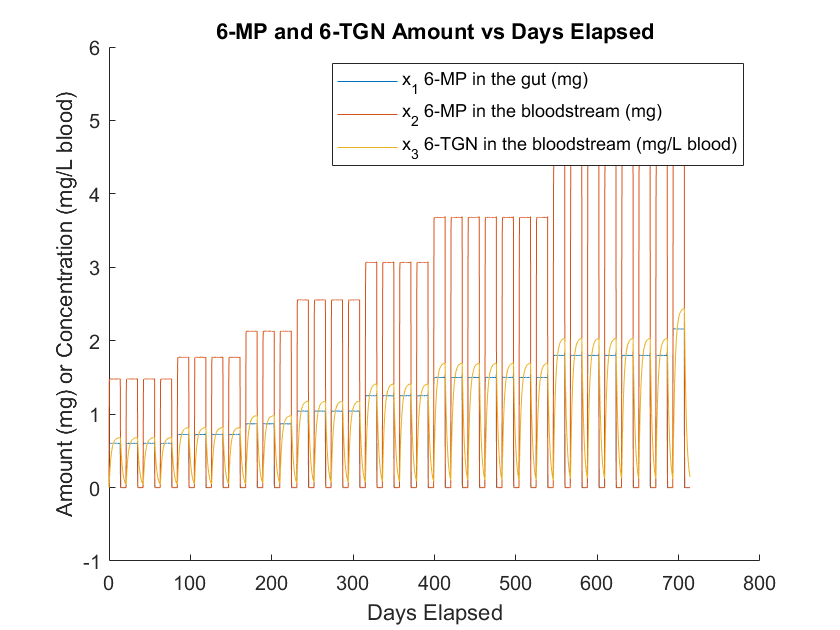

figure()
hold on
xlabel('Days Elapsed')
ylabel('Amount (mg) or Concentration (mg/L blood)')
title("6-MP and 6-TGN Amount vs Days Elapsed")
plot(t_nominal,x_nominal(:,1))
plot(t_nominal,x_nominal(:,2))
plot(t_nominal,x_nominal(:,3))
legend(...
    "x_1 6-MP in the gut (mg)", ...
    "x_2 6-MP in the bloodstream (mg)", ...
    "x_3 6-TGN in the bloodstream (mg/L blood)" ...
)
hold off

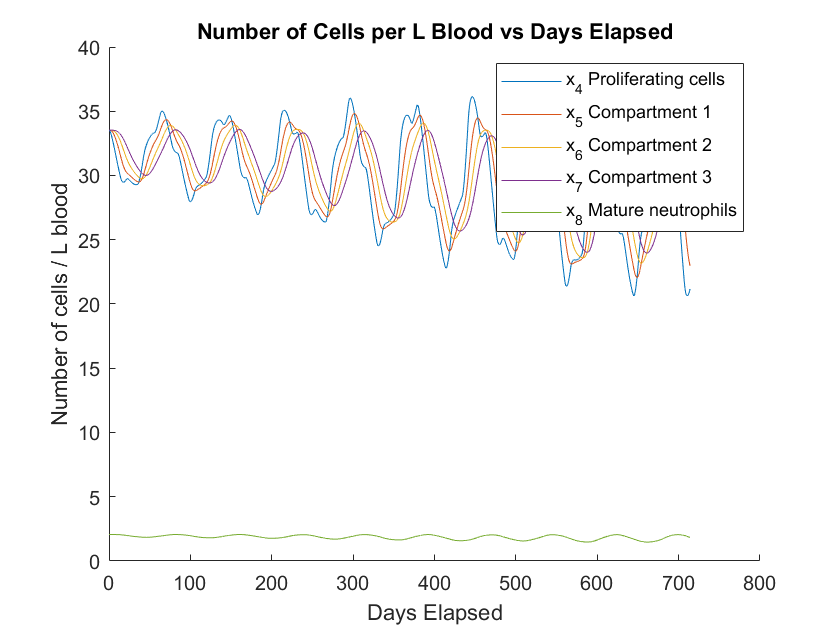


figure()
hold on
xlabel('Days Elapsed')
ylabel('Number of cells / L blood')
title("Number of Cells per L Blood vs Days Elapsed")
plot(t_nominal,x_nominal(:,4))
plot(t_nominal,x_nominal(:,5))
plot(t_nominal,x_nominal(:,6))
plot(t_nominal,x_nominal(:,7))
plot(t_nominal,x_nominal(:,8))
legend(...
    "x_4 Proliferating cells", ...
    "x_5 Compartment 1", ...
    "x_6 Compartment 2", ...
    "x_7 Compartment 3", ...
    "x_8 Mature neutrophils" ...
)
hold off

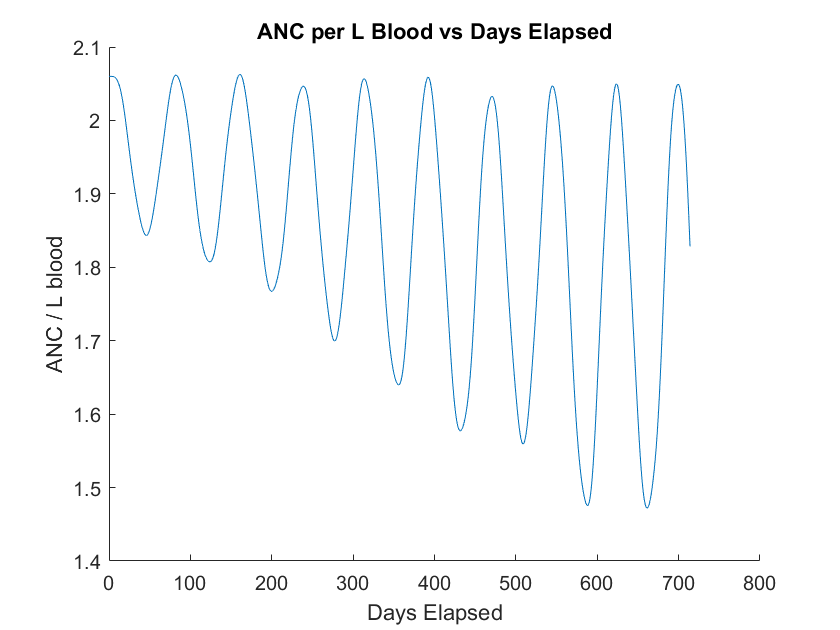


figure()
hold on
xlabel('Days Elapsed')
ylabel('ANC / L blood')
title("ANC per L Blood vs Days Elapsed")
plot(t_nominal,rho)
hold off

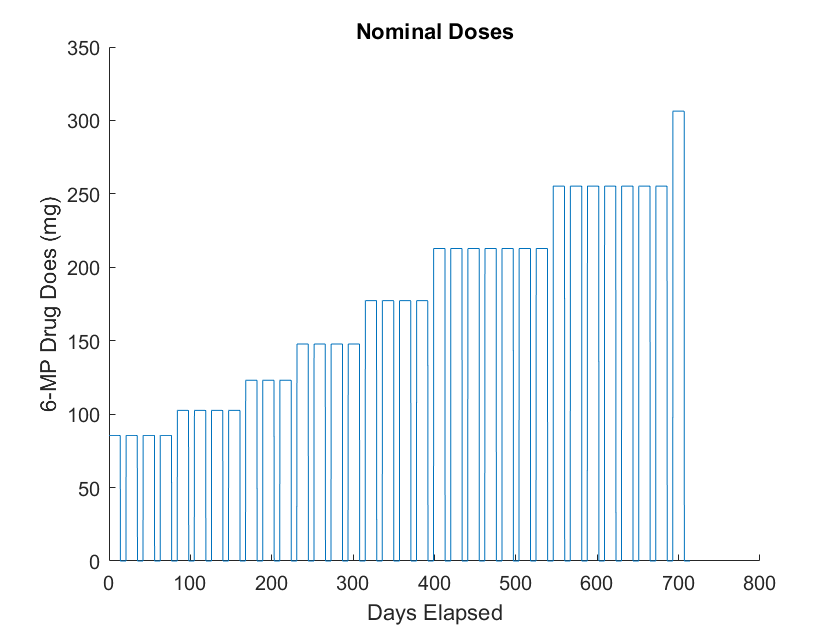


figure()
hold on
xlabel('Days Elapsed')
ylabel('6-MP Drug Does (mg)')
title("Nominal Doses")
plot(t_nominal,u_nominal)
hold off

## 1.4 Adaptive Model Predictive Controller

% Simulation Length
N_cycles=5;
N_cyclepred=3;

t_s = step_size;
t_end = N_cycledays*N_cycles;
N_steps = t_end / t_s;
time = (0:t_s:t_end);

% Generate disturbance and measurement noise given covariances Q,R
sigQ = 0.01;
sigR = 0.774341747;
Q_const = sigQ * eye(n);
R_const = sigR * eye(m);

d = zeros([n 1 N]);                 % disturbance
mn = zeros([m 1 N]);                % measurement noise

for i = 1:N_steps
    d(:,:,i) = Q_const * randn([n,1]);
    mn(:,:,i) = R_const * randn([m,1]);
end
clear sigQ sigR Q_const R_const i

% Simulate System
n_theta = length(theta);
x_calc = zeros([n,1,N_steps+1]);
y_calc = zeros([m,1,N_steps+1]);
theta_calc = zeros([n_theta,1,N_cycles+1]);
u_calc = zeros([1,N_cycles]);

x_calc(:,:,1) = x0;
y_calc(:,:,1) = g_nonlin(x0);
theta_calc(:,:,1) = theta_guess;

for k=1:N_cycles
    prev_i = N_cycledays*(k-1);
    if k == 1
        prev_i = 1;
    end
    
    disp(prev_i)
    
    % find vector p_star that minimizes measurement error
    % use nonlinear function f and g here
    f = @(p)calc_p_star_jost(p, theta, x0, u_calc, prev_i, N_cycledays, N_drugdays);
    [theta_star, fval] = fmincon(f,theta_calc(:,:,k),[],[],[],[],repmat(1e-5, [n_theta 1]),repmat(1e3, [n_theta 1]));
    
    % find input u that minimizes output error using best parameter guess
    % (the input u does not have access to p_actual)
    g = @(u)calc_adaptive_control_jost(...
        theta_star, rho, x_calc(:,:,prev_i), u, 10, 0.001, N_cyclepred, 0, k, N_cycledays, N_drugdays ...
    );
    [u_star, gval] = fmincon(g,repmat(u_calc(k), [N_cyclepred 1]));
    
    u_calc(k) = u_star(1);
    theta_calc(:,:,k+1) = theta_star;
    
    % this is suppose to be the true system that the controller doesn't
    % know - controller is trying to learn the underlying true system
    for i=prev_i:N_cycledays*k - 1
        x_calc(:,:,i+1) = jost(i,x_calc(:,:,i), u_calc(k),theta,N_cycledays,N_drugdays);
        y_calc(:,:,i+1) = g_nonlin(x_calc(:,:,i+1));
    end
end

     1




Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


## 2.2 Controller Plots

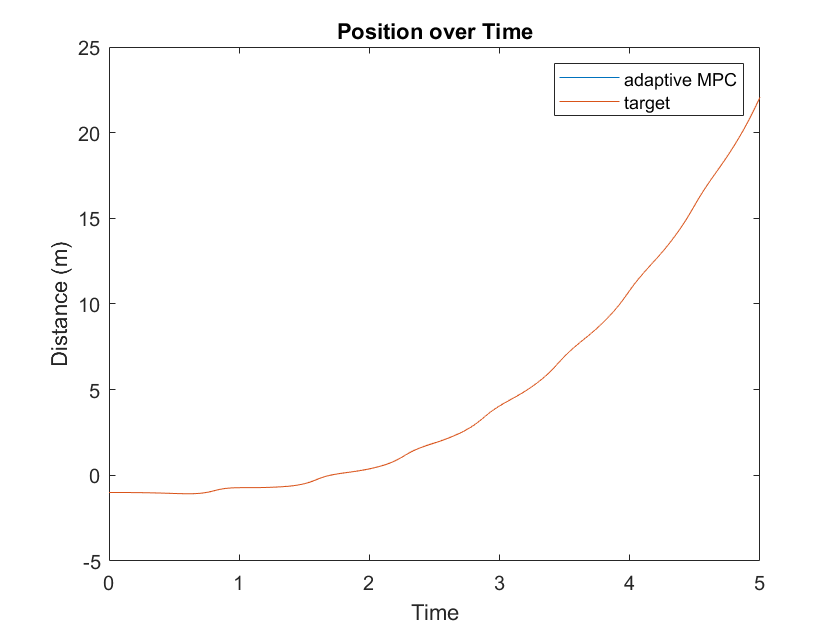

x1 = reshape(x_calc(1,1,:),[1 N+1]);
x2 = reshape(x_calc(2,1,:),[1 N+1]);
x3 = reshape(x_calc(3,1,:),[1 N+1]);
x4 = reshape(x_calc(4,1,:),[1 N+1]);
x_nom1 = reshape(x_nominal(1,1,:),[1 N+1]);
x_nom2 = reshape(x_nominal(2,1,:),[1 N+1]);
x_nom3 = reshape(x_nominal(3,1,:),[1 N+1]);
x_nom4 = reshape(x_nominal(4,1,:),[1 N+1]);

figure(1)
plot(time,x1)
hold on
plot(time,x_nom1)
title('Position over Time')
xlabel('Time')
ylabel('Distance (m)')
legend('adaptive MPC','target')
hold off

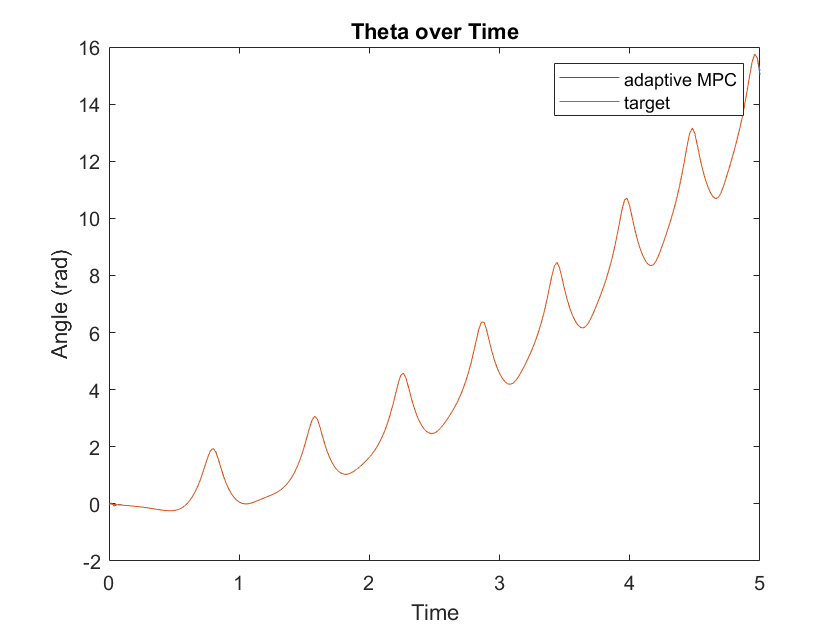


figure(2)
plot(time,x2)
hold on
plot(time,x_nom2)
title('Theta over Time')
xlabel('Time')
ylabel('Angle (rad)')
legend('adaptive MPC','target')
hold off

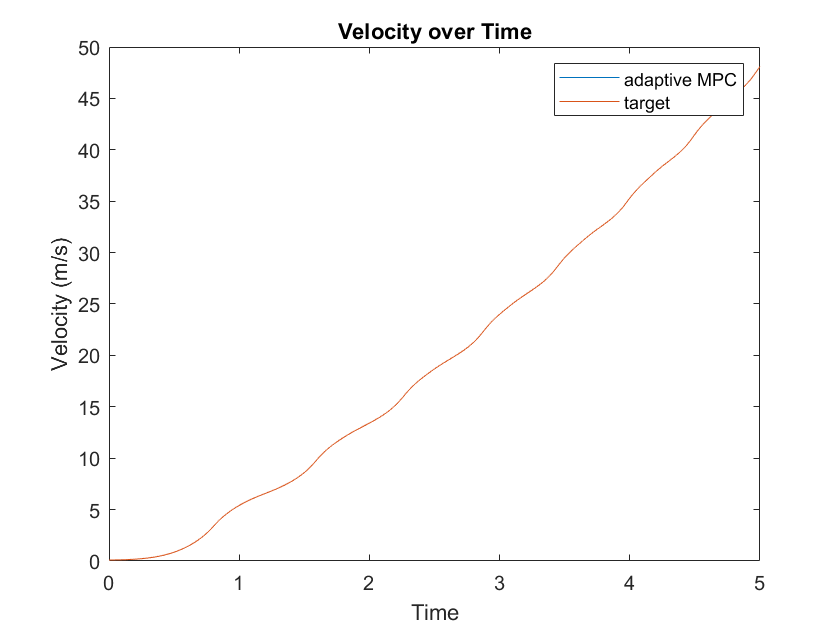


figure(3)
plot(time,x3)
hold on
plot(time,x_nom3)
title('Velocity over Time')
xlabel('Time')
ylabel('Velocity (m/s)')
legend('adaptive MPC','target')
hold off

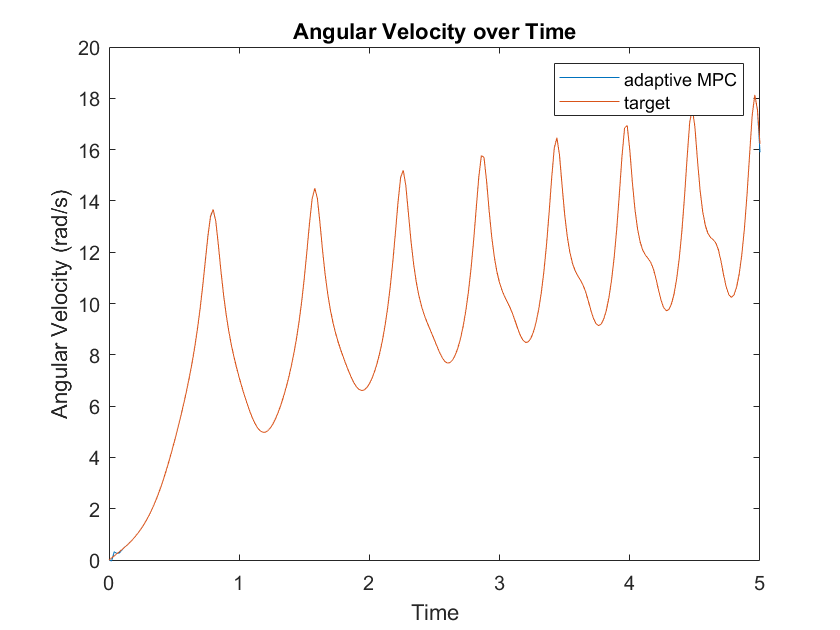


figure(4)
plot(time,x4)
hold on
plot(time,x_nom4)
title('Angular Velocity over Time')
xlabel('Time')
ylabel('Angular Velocity (rad/s)')
legend('adaptive MPC','target')
hold off

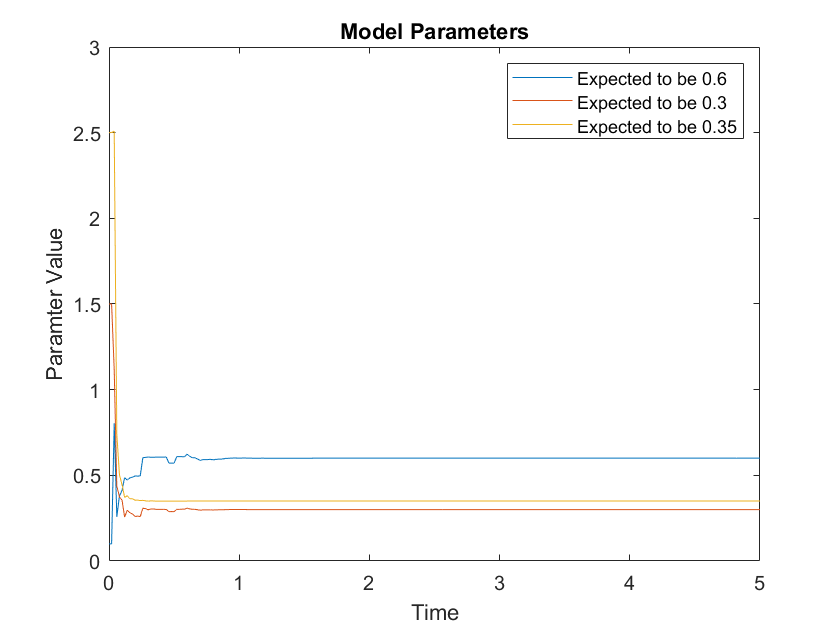


p1 = reshape(p_calc(1,1,:),[1 N+1]);
p2 = reshape(p_calc(2,1,:),[1 N+1]);
p3 = reshape(p_calc(3,1,:),[1 N+1]);
figure(5)
plot(time,p1)
hold on
plot(time,p2)
hold on
plot(time,p3)
title('Model Parameters')
xlabel('Time')
ylabel('Paramter Value')
legend('Expected to be 0.6','Expected to be 0.3', 'Expected to be 0.35')
hold off

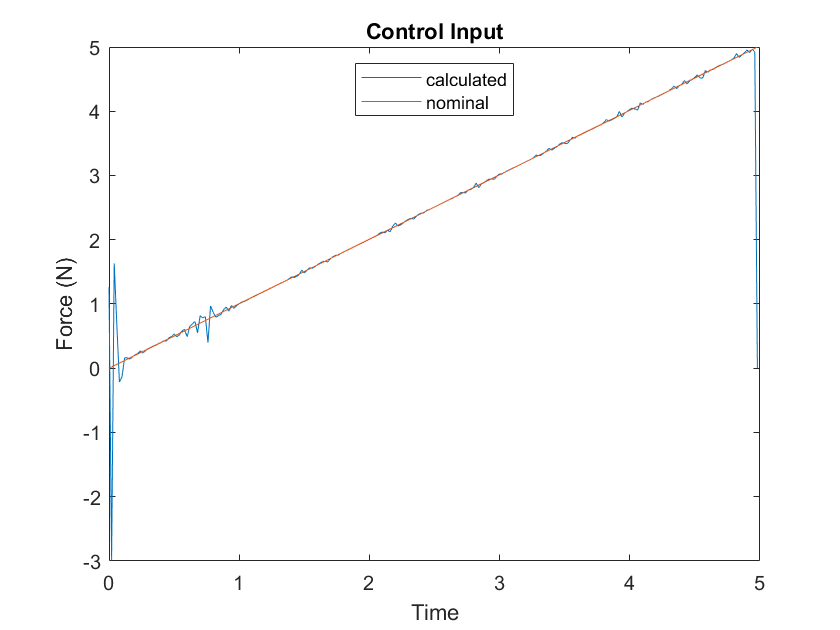


figure(6)
plot(time(:,1:end-1),u_calc)
hold on
plot(time(:,1:end-1),u_nominal)
title('Control Input')
xlabel('Time')
ylabel('Force (N)')
l = legend('calculated','nominal');
l.Location = "north";
hold off